clc, clear, close all;

## Load data

base_sample_rate = 1000;
emg_sample_rate = 1000;

AddPaths()

Linux


emg_file = 'EMG_SECOND_PLAY_CHOPIN_C.txt';
[~, emg_muscle1, emg_muscle2] = ReadData(emg_file, emg_sample_rate, base_sample_rate);

emg_file = 'EMG_MVC_001.txt';
[~, mvc_muscle1, mvc_muscle2] = ReadData(emg_file, emg_sample_rate, base_sample_rate);

## Convert to mV

n = 12; VCC = 3; Gemg = 1000;
DigTomV = @(adc) (((adc./2.^n - 1/2) .* VCC) ./ Gemg) * 1000;
x_start = 50000; x_stop = x_start+999;

mV_muscle1 = DigTomV(emg_muscle1(x_start:x_stop)');
mV_muscle2 = DigTomV(emg_muscle2(x_start:x_stop)');
mV_mvc1 = DigTomV(mvc_muscle1');
mV_mvc2 = DigTomV(mvc_muscle2');

# Filter data

### Settings

% Bandpass setting
f_low = 10;     % Lower cutoff frequency
f_high = 250;   % Upper cutoff frequency
freq_range = [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)];
filter_order = 8;
samples = length(mV_muscle1);

### Filters

% Design the Butterworth bandpass filter
[b_bp, a_bp] = butter(filter_order, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');

% Design the Butterworth lowpass filter
[b_lp, a_lp] = butter(filter_order, f_high/(emg_sample_rate/2), 'low');

### Apply Filters

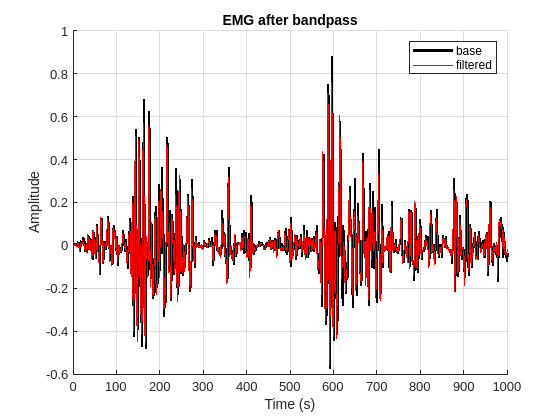

bp_muscle1 = filtfilt(b_bp, a_bp, mV_muscle1);
figure; hold on
plot(mV_muscle1, 'k', 'LineWidth', 2);  
plot(bp_muscle1, 'r', 'LineWidth', 1);
xlabel('Time (s)'); ylabel('Amplitude');
title('EMG after bandpass');
xlim([0, samples])
legend("base", "filtered");
grid on;
hold off

rect_muslce1 = abs(mV_muscle1);    % Full-Wave Rectification
lp_muscle1 = filtfilt(b_lp, a_lp, rect_muslce1);
figure; hold on
%plot(mV_muscle1, 'k', 'LineWidth', 1);
plot(lp_muscle1, 'r', 'LineWidth', 1);
xlabel('Time (s)'); ylabel('Amplitude');
title('EMG after Linearization');
xlim([0, samples])
legend("base", "envelope");

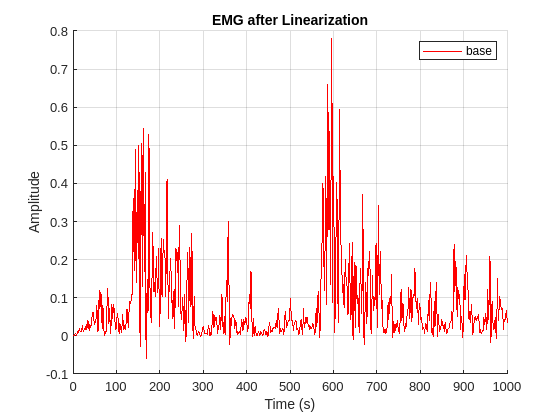

grid on;
hold off

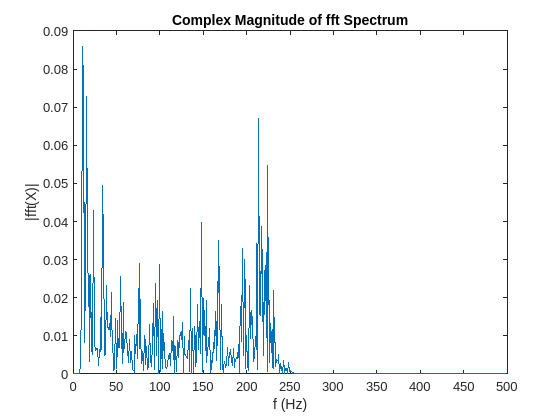

bp_muscle1 = filtfilt(b_bp, a_bp, lp_muscle1);
m = length(bp_muscle1);       % original sample length
n = pow2(nextpow2(m));  % transform length
y = fft(bp_muscle1,n);        % DFT of signal
f = (0:n-1)*(emg_sample_rate/n);
power = abs(y).^2/n;
plot(f(1:floor(n/2)),power(1:floor(n/2)))

title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)"); ylabel("|fft(X)|")

% filt_muscle1 = filtfilt(b_but, a_but, mV_muscle1);
% filt_muscle2 = filtfilt(b_but, a_but, mV_muscle2);
% filt_mvc1 = filtfilt(b_but, a_but, mV_mvc1);
% filt_mvc2 = filtfilt(b_but, a_but, mV_mvc2);

## Normalize data

% norm_muscle1 = filt_muscle1/max(filt_mvc1);
% norm_muscle2 = filt_muscle2/max(filt_mvc2);
% 
% figure; hold on
% plot(norm_muscle1, 'r', 'LineWidth', 1);
% plot(norm_muscle2, 'b', 'LineWidth', 1);
% title("Filtered function");
% legend("msucle1", "muscle2");
% hold off

## Function

function [sync, muscle1, muscle2] = ReadData(filename_EMG, emg_sample_rate, base_sample_rate)
    % "column": ["index", "overbodig", "sync", "spier 1", "spier 2"]
    data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
    sync = data(:, 3);
    muscle1 = data(:, 4);
    muscle2 = data(:, 5);
end